## Zadanie 3) Optymalizacja regulatora PD po module

#### a) Optymalizacja bez ograniczeń

Wykorzystując funkcje fminsearch, należy wykonać optymalizację nastaw regulatora PD aby zapas po module był M≥2

gdzie:

obiekt G(s)=1s3+3s2+4s+2

regulator  Gr(s)=Kp+Kds

Przykład

clear

Gs2 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



 
 Iteration   Func-count     min f(x)         Procedure
     0            1             -Inf         
     1            3             -Inf         initial simplex
     2            7             -Inf         shrink
     3           11             -Inf         shrink
     4           15             -Inf         shrink
     5           19             -Inf         shrink
     6           23             -Inf         shrink
     7           27             -Inf         shrink
     8           31             -Inf         shrink
     9           35             -Inf         shrink
    10           39             -Inf         shrink
    11           43             -Inf         shrink
    12           47             -Inf         shrink
    13           51             -Inf         shrink
    14           55             -Inf         shrink
    15           59             -Inf         shrink
    16           63             -Inf         shrink
    17           67             -Inf         shrink
    

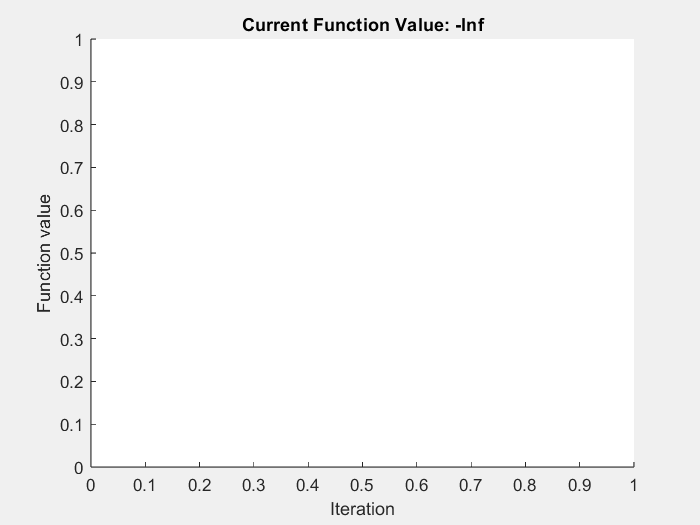

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -Inf 



x =      1     0


fval = -Inf

exitflag = 0

Gs2 = tf([1], [1 3 4 2])
x0 = [1, 0]; %

figure
options = optimset('Display','iter','PlotFcns', @optimplotfval);
[x, fval, exitflag] = fminsearch(@ident, x0, options)

G1 = tf([1], [1 3 4 2]) % System

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



C = pid(x(1), 0, x(2)) % Controller

C =
 
  Kp = 1
 
P-only controller.




G2_loop = feedback(C*G1, 1)

G2_loop =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 3
 
Continuous-time transfer function.



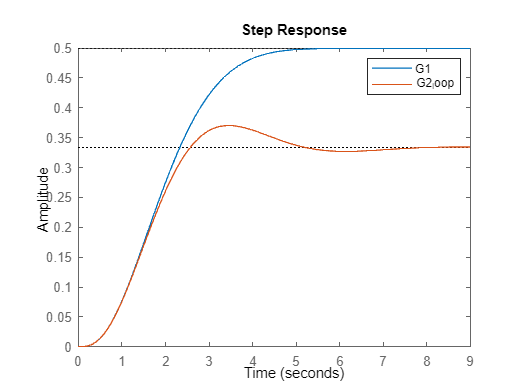


figure
step(G1, G2_loop);
legend('G1', 'G2_loop')


G2 = C*G1;
[Gm, Pm, Wcg, Wcp] = margin(G2)

Gm = 10.0000

Pm = Inf

Wcg = 2.0000

Wcp = NaN


[z, p, k] = tf2zp(G2_loop.Numerator{1, 1}, G2_loop.Denominator{1, 1})


z =

  0×1 empty double column vector



p =   -1.6823 + 0.0000i
  -0.6588 + 1.1615i
  -0.6588 - 1.1615i


k = 1

b)    Optymalizacja z ograniczeniami

Nałożyć ograniczenia na współczynniki dla regulatora rzeczywistego

clear
Gs2 = tf([1], [1 3 4 2])

Gs2 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



global G1
G1 = Gs2;
x0 = [1, 0];

opts = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp');
figure;
x = fmincon(@ident, x0, [], [], [], [], [], [], @ogr, opts)

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0           3    6.400021e+01     1.000e+00     1.000e+00     0.000e+00     8.580e+06  


    1           6    3.755411e+00     1.000e+00     1.000e+00     1.600e+02     8.966e+00  


    2          27    3.755399e+00     1.000e+00     1.628e-03     1.462e-02     6.382e-02  


    3          36    3.755399e+00     1.000e+00     4.035e-02     6.035e-05     6.382e-02  

Converged to an infeasible point.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance but constraints are not
satisfied to within the value of the constraint tolerance.

<stopping criteria details>


x =   161.0013   -0.0146


G1 = tf([1], [1 3 4 2]) % System

G1 =
 
            1
  ---------------------
  s^3 + 3 s^2 + 4 s + 2
 
Continuous-time transfer function.



C = pid(x(1), 0, x(2)) % Controller

C =
 
             
  Kp + Kd * s
             

  with Kp = 161, Kd = -0.0146
 
Continuous-time PD controller in parallel form.




G2_loop = feedback(C*G1, 1)

G2_loop =
 
        -0.0146 s + 161
  ---------------------------
  s^3 + 3 s^2 + 3.985 s + 163
 
Continuous-time transfer function.



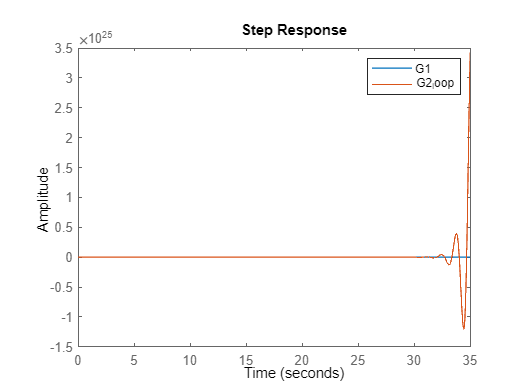


figure
step(G1, G2_loop);
legend('G1', 'G2_loop')


G2 = C*G1;
[Gm, Pm, Wcg, Wcp] = margin(G2)

Gm = 0.0621

Pm = -57.8851

Wcg = 2.0000

Wcp = 5.4055


[z, p, k] = tf2zp(G2_loop.Numerator{1, 1}, G2_loop.Denominator{1, 1})

z = 1.1027e+04

p =   -6.3799 + 0.0000i
   1.6900 + 4.7637i
   1.6900 - 4.7637i


k = -0.0146

function blad = ident(x)
t = 0:0.01:10;
G1 = tf([1], [1 3 4 2]);
C = pid(x(1), 0, x(2)); % Controller
G2 = C*G1;
[Gm, Pm, Wcg, Wcp] = margin(G2);
e = (Gm-2)^2;
blad = e;
end

function [c, ceq] = ogr(x)
    ceq = [];
    c = 0;
    global G1

    if 0<x(1) && x(1)<5 && 0<x(2) && x(2)<10
        reg = pid(x(1), 0, x(2));
        G1c = feedback(reg*G1, 1);
        c = 1 - 2*isstable(G1c);
    else
        c = 1;
    end %if
end %ogr